L = 0.2;
m = 0.25;
g = 9.81;
o = sqrt(3*m*g*L / (5*m*L^2))

o = 5.4249

o_t = 2*pi;
k_t = o_t^2 * 5*m*L^2 - 3*m*g*L

k_t = 0.5024

Equations of motion

Introduce a new variable for angular velocity


$$\omega = \dot{\theta}$$


so that the *state* of our system is the vector


$$\left\lbrace \begin{array}{c} \omega \\ \theta  \end{array}\right\rbrace$$


and the derivative of the state, as a function of the state, is


$$\dot{\omega} = \frac{-k_t \theta -3 m g L \sin(\theta)}{5mL^2$$



$$\dot{\theta} = \omega$$


function dot_state = pendulum(t, state)
    % Unpack state vector
    omega = state(1);
    theta = state(2);
    % Parameters
    L = 0.2;
    m = 0.25;
    g = 9.81;
    k_t = 0.5024;
    % EOM model
    dot_omega = (-k_t*theta - 3*m*g*L*sin(theta))/(5*m*L^2);
    dot_theta = omega;
    % Pack derivative of state vector for output
    dot_state = [dot_omega ; dot_theta];
end


solv

x0 = [0 1];
tspan = [0 5];
[tout, yout] = ode45(@pendulum, tspan, x0 );
figure(1)
clf;
plot(tout,yout(:,2))
hold on
om_t = sqrt((k_t + 3*m*g*L) / (5*m*L^2))

om_t = 6.2832

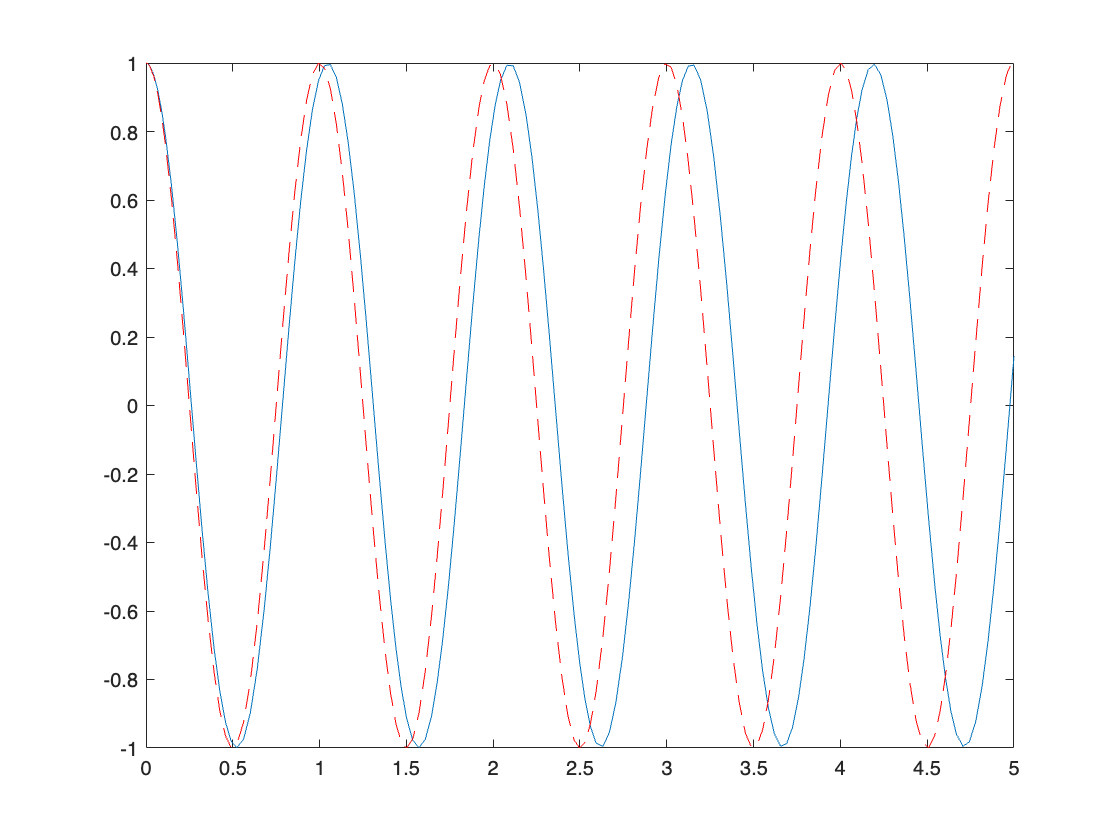

plot(tout, x0(2)*cos(om_t*tout), 'r--')